**Practicas parte 2**

Problemas tema 3

Ej 1

[r,p,k]=residuez([1,0.3],[1,-0.7]) %Vas añadiendo en orden creciente del grado, primera parte numerados y segunda divisor, si te dan z elevado a algo positivo dividir por lo de abajo para que den todo negativos

r = 1.4286

p = 0.7000

k = -0.4286

%Se puede hacer la transformada a X(z) tal que [b,a]=residuez(r,p,k)
N=20; %simplemente pillar un numero para el cual se ve que la funcion se estabiliza, IMP
n=linspace(0,N-1,N);
h1=r(1)*p(1).^n.*fEsc(n,0)+k(1)*fDelta(n,0); %Ver valores de r,p,k y escribir esto sobre ello/ r*p*n*fEsc+fDelta*k

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


h1t=fDelta(n,0)+0.7.^(n-1).*fEsc(n,1);

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


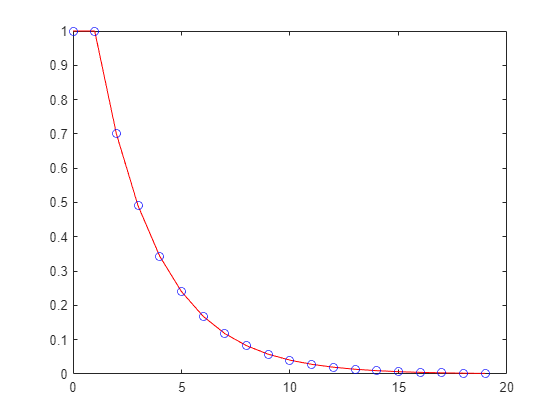

plot(n,h1,'r',n,h1t,'bo');

Ej 2

[r,p,k]=residuez([1,0.3],[1,-0.7,0.49])

r =    0.5000 - 0.5361i
   0.5000 + 0.5361i


p =    0.3500 + 0.6062i
   0.3500 - 0.6062i



k =

     []



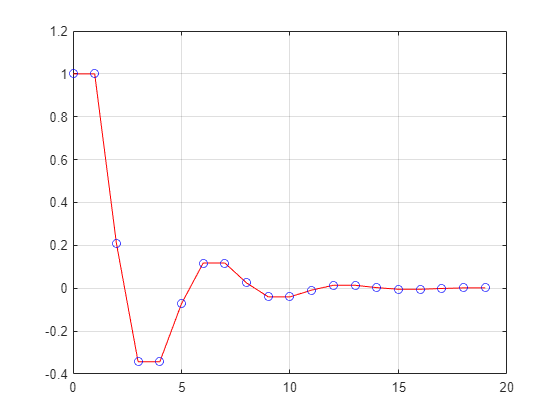

N=20;
n=linspace(0,N-1,N);
h2=r(1)*p(1).^n.*fEsc(n,0)+r(2)*p(2).^n.*fEsc(n,0); %como k es nada no se pone, si no, sumar k multiplicado por delta(n,0)
h2t=0.7.^n.*(1.073.*sin(pi/3*n)+cos(pi/3*n)).*fEsc(n,0); %la solucion obtenida realmente es x[n], no te ralles con la h, no es un filtro
plot(n,h2,'r',n,h2t,'bo');grid

Ej 3

[r,p,k]=residuez([1,-0.48],[1,-1.6,0.64])

r =    0.6000 + 0.0000i
   0.4000 - 0.0000i


p =    0.8000 + 0.0000i
   0.8000 - 0.0000i



k =

     []



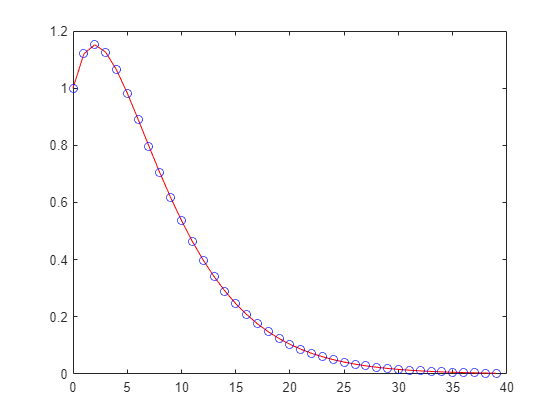

N=40;
n=linspace(0,N-1,N);
h3=r(1)*p(1).^n.*fEsc(n,0)+r(2)*(n+1).*p(2).^n.*fEsc(n,-1); %cuando los polos (p) son iguales se hace esto, si hay mas de grade 2 ni puta
h3t=0.8.^n.*(1+0.4*n).*fEsc(n,0);
plot(n,real(h3),'r',n,h3t,'bo');

[r,p,k]=residuez([1,0.3],[1,-0.6,0.25])

r =    0.5000 - 0.7500i
   0.5000 + 0.7500i


p =    0.3000 + 0.4000i
   0.3000 - 0.4000i



k =

     []



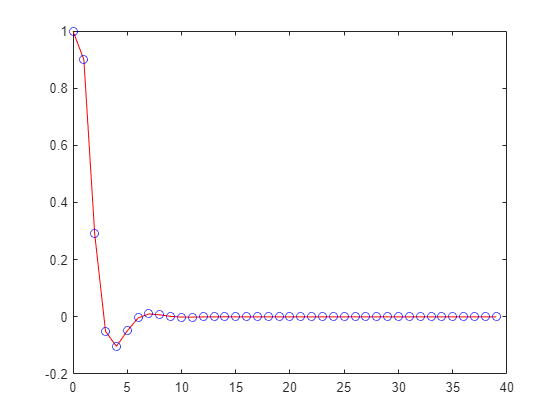

h4=r(1)*p(1).^n.*fEsc(n,0)+r(2)*p(2).^n.*fEsc(n,0);
h4t=(0.5.^n).*(cos(0.9273.*n)+1.5*sin(0.9273.*n)).*fEsc(n,0);
plot(n,real(h4),'r',n,h4t,'bo');

Problemas ventanas

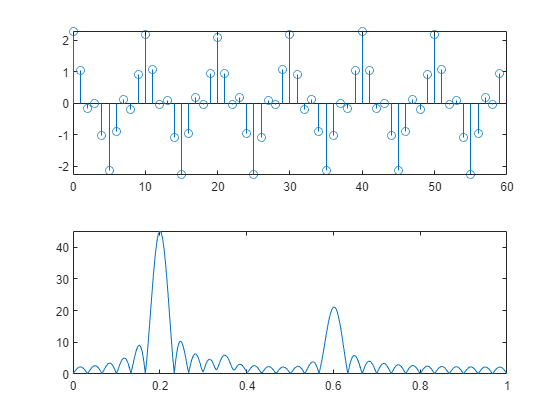

N=60;
n=linspace(0,N-1,N);
x=1.5*cos(0.2*pi*n)+0.1*cos(0.35*pi*n)+0.7*cos(0.6*pi*n);
w=linspace(0,pi,301);
X=fDTFT(x,n,w);
subplot(211);stem(n,x);subplot(212);plot(w/pi,abs(X)); %Para que asi vaya del 0 al 1 y quede mas bonito

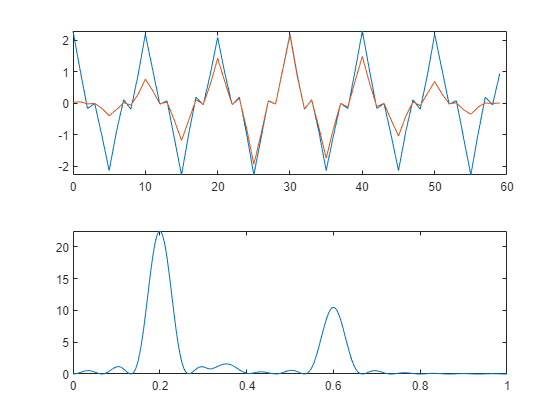

xB=x.*triang(N)'; %Ventana Barlett/Triangular (Solo tienes que multiplicar la traspuesta de la ventana de N, a la x en tiempo
XB=fDTFT(xB,n,w);
figure;subplot(211);plot(n,x,n,xB);subplot(212);plot(w/pi,abs(XB));

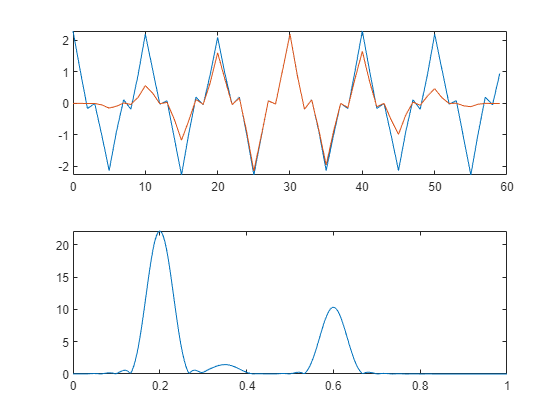

xHnn=x.*hann(N)'; %Ventana Hanning
XHnn=fDTFT(xHnn,n,w);
figure;subplot(211);plot(n,x,n,xHnn);subplot(212);plot(w/pi,abs(XHnn));

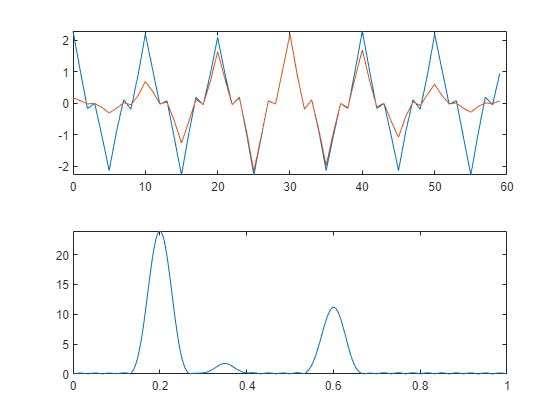

xHmm=x.*hamming(N)'; %Ventana Hamming
XHmm=fDTFT(xHmm,n,w);
figure;subplot(211);plot(n,x,n,xHmm);subplot(212);plot(w/pi,abs(XHmm));

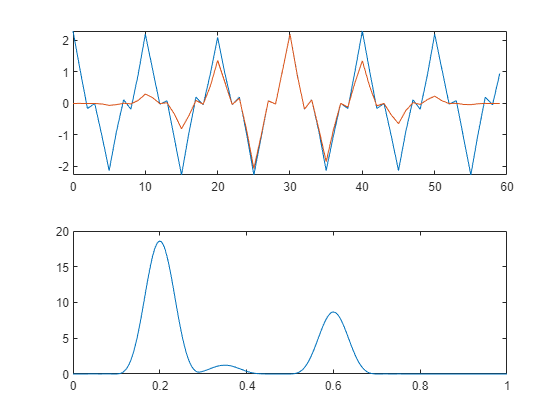

xBlack=x.*blackman(N)'; %Ventana Blackman
XBlack=fDTFT(xBlack,n,w);
figure;subplot(211);plot(n,x,n,xBlack);subplot(212);plot(w/pi,abs(XBlack));

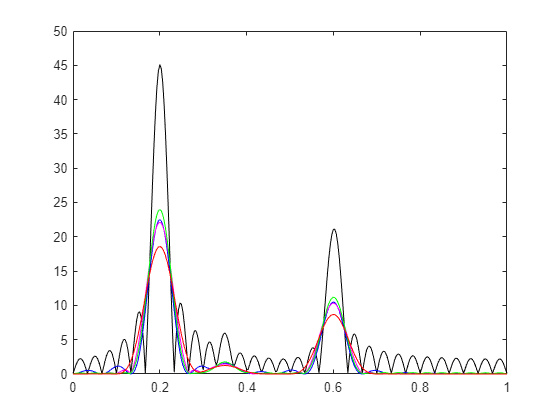

%Lo del apostrofe es para invertirlas que vienen en columnas en lugar de
%en fila
%Tambien puedes wvtool(x) y te muestra las dos de golpe en una ventana
%externa, pero queda mas bonito de esta manera y mejor, al hacer la fDTFT,
%que si se hiciera la fft
subplot(111);plot(w/pi,abs(X),'k',w/pi,abs(XB),'b',w/pi,abs(XHnn),'m',w/pi,abs(XHmm),'g',w/pi,abs(XBlack),'r'); %Para comparar los resultados en una

Problemas filtros FIR

N=60; %Esto lo que te pidan, sino un numero lo suficientemente grande
n=linspace(0,N-1,N);
w=linspace(0,pi,301);
x=1.5*cos(0.2*pi*n)+0.1*cos(0.35*pi*n)+0.7*cos(0.6*pi*n);
X=fDTFT(x.*hamming(N)',n,w);

Filtro paso bajo

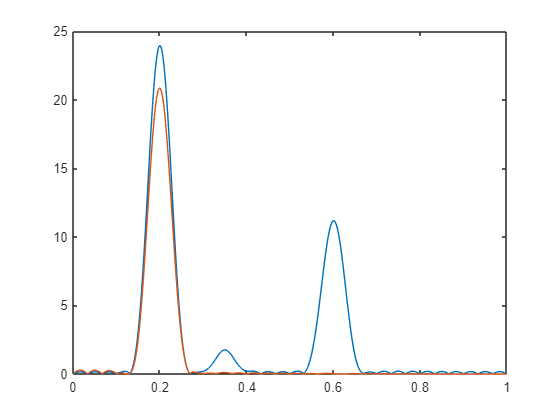

%Si el filtro se hace con multiplos de 10 daria bien siempre pero lo que
%tienes que tener en cuenta es el numero de cifras que quieres especificar
%Fijarse en 1/Nh, para la resolucion que se necesita mas o menos, con
%numeros no multiplos de 10 no filtra la componente 0.2
Nh=24; %Tienen que ser numeros pares, porque sino hace cosas raras, si cosas raras tambien puedes pedir que haga ifft simetrica
nh=linspace(0,Nh-1,Nh);
nhf=nh*2/Nh; %frecuencias normalizadas
H=fLowPass(nhf,0.2,0.26); %Empieza probando con frecuencias especificas y luego vas modificando, hasta que quede bien
h  = ifft(H);
%En la funcion es importante meter todos los datos normalizados osea
%frecuencia/pi, por eso se ajusta la nh antes


%hacer el ajuste para los valores que se pierden, por convolucion
Ne=(N+Nh-1); 
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
y=ifft(fft(xe).*fft(h,Ne));
y=y(Nh:Ne); %Quitar los primeros valores que estaban mal
Y=fDTFT(y.*hamming(N)',n,w);

%Representacion en tiempo
subplot(111);plot(n+Nh/2,x,n,real(y),n+Nh/2,1.5*cos(0.2*pi*n),'o'); %Azul funcion sin filtrar, puntos funcion que deberia de salir, naranja funcion filtrada
%Representacion en frecuencia
subplot(111);plot(w/pi,abs(X),w/pi,abs(Y)); %Naraja filtrada, azul filtrada, las dos pasadas por ventana Hamming

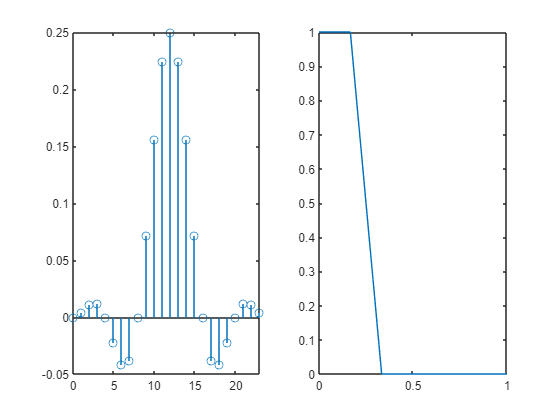

%Representacion del filtro
subplot(121);stem(nh,real(h));subplot(122);plot(nhf,abs(H));axis([0 1 0 1]);

Filtro paso banda

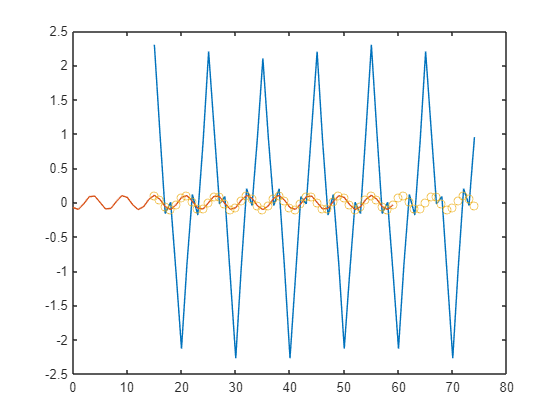

Nh=30;
nh=linspace(0,Nh-1,Nh);
nhf=nh*2/Nh;
H1=fLowPass(nhf,0.26,0.3); %Hacer un filtro pasa bajo, que NO tenga la parte que se quiere coger
H2=fLowPass(nhf,0.45,0.55); %Hacer filtro paso bajo, que englobe a la parte que se quiere coger
%H=exp(-j*2*pi*nh/2)-(H2-H1); %Esto seria para filtro banda eliminada
H=H2-H1; %Filtro paso banda
h=ifft(H);

Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
y=ifft(fft(xe).*fft(h,Ne));
y=y(Nh:Ne);
Y=fDTFT(y.*hamming(N)',n,w);

%Representacion en tiempo
subplot(111);plot(n+Nh/2,x,n,real(y),n+Nh/2,0.1*cos(0.35*pi*n),'o'); %Azul funcion sin filtrar, puntos funcion que deberia de salir, naranja funcion filtrada

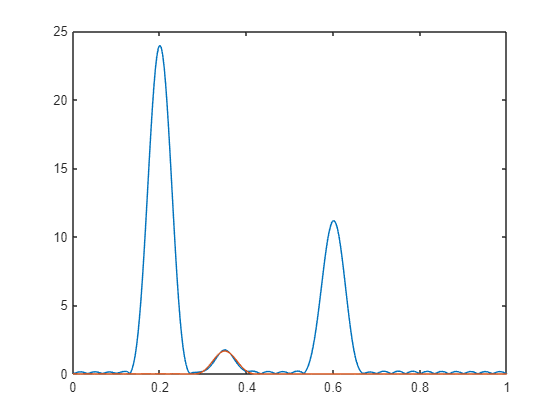

%Representacion en frecuencia
subplot(111);plot(w/pi,abs(X),w/pi,abs(Y)); %Naraja filtrada, azul filtrada, las dos pasadas por ventana Hamming

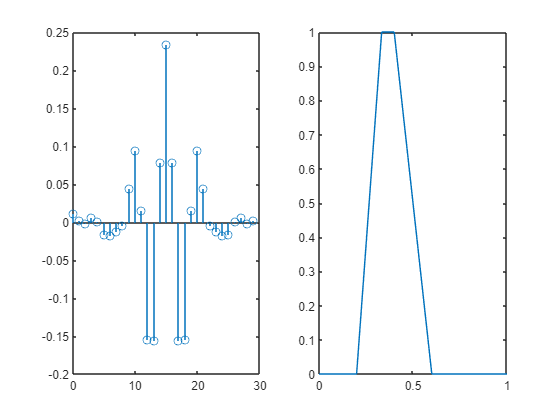

%Representacion filtro
subplot(121);stem(nh,real(h));subplot(122);plot(nhf,abs(H));axis([0 1 0 1]);

Filtro paso alto

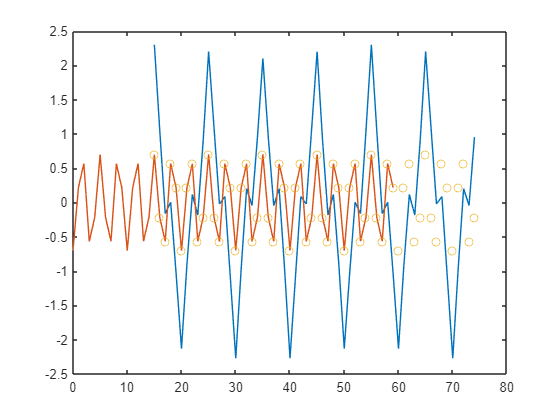

Nh=30;
nh=linspace(0,Nh-1,Nh);
nhf=nh*2/Nh;
H=exp(-j*2*pi*nh/2)-fLowPass(nhf,0.45,0.55); %filtro paso alto, se filtra todo lo que estaria en el de paso bajo al hacerlo asi, entonces solo queda lo otro
h=ifft(H);

Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
y=ifft(fft(xe).*fft(h,Ne));
y=y(Nh:Ne);
Y=fDTFT(y.*hamming(N)',n,w);

%Representacion en tiempo
subplot(111);plot(n+Nh/2,x,n,real(y),n+Nh/2,0.7*cos(0.6*pi*n),'o'); %Azul funcion sin filtrar, puntos funcion que deberia de salir, naranja funcion filtrada

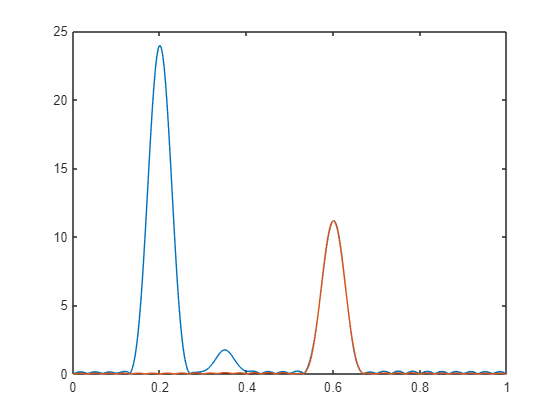

%Representacion en frecuencia
subplot(111);plot(w/pi,abs(X),w/pi,abs(Y)); %Naraja filtrada, azul filtrada, las dos pasadas por ventana Hamming

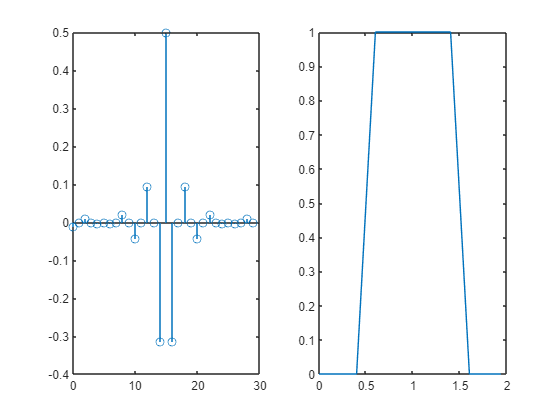

%Representacion filtro
subplot(121);stem(nh,real(h));subplot(122);plot(nhf,abs(H));;

Problemas Filtro IIR

N=100;
n=linspace(0,N-1,N);
x=1.5*cos(0.2*pi*n)+0.1*cos(0.35*pi*n)+0.7*cos(0.6*pi*n);
w=linspace(0,pi,301);
X=fDTFT(x.*hamming(N)',n,w);
%Luego hacer la misma mierda para todo y una vez hecho simplemente ir
%cambiando valores hasta que apenas 

Filtro Butterworth

%Primero orden del filtro, despues frecuencia de corte normalizada (frecuencia/pi)
[b,a]=butter(6,0.26); %Filtro paso bajo
%freqz(b,a);%Para ver las frecuencias del filtro directamente
hlButter=filter(b,a,fDelta(n,0)); 

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Nh=max(find(abs(hlButter)>max(hlButter)/20)); %Con esto obtienes cuantas muestras tienes que eliminar
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
ylButter=filter(b,a,xe);
ylButter=ylButter(Nh:Ne);
[b,a]=butter(2,[0.33,0.36]); %Filtro paso banda %Paso banda eliminada seria butter(N,[w1,w2],"stop");
hbButter=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Nh=max(find(abs(hbButter)>max(hbButter)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
ybButter=filter(b,a,xe);
ybButter=ybButter(Nh:Ne);
[b,a]=butter(6,0.55,"high"); %Filtro paso alto
hhButter=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


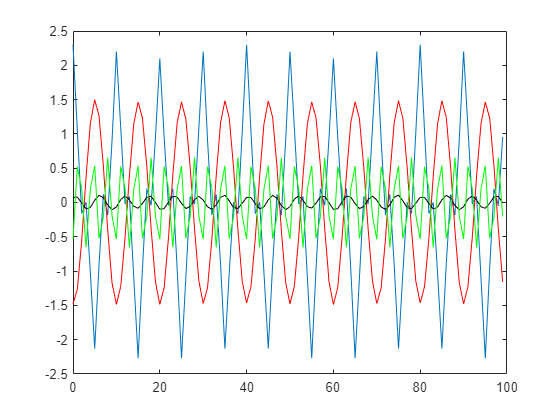

Nh=max(find(abs(hhButter)>max(hhButter)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
yhButter=filter(b,a,xe);
yhButter=yhButter(Nh:Ne);
%Representacion en tiempo
subplot(111);plot(n,x,n,ylButter,'r',n,ybButter,'black',n,yhButter,'g');

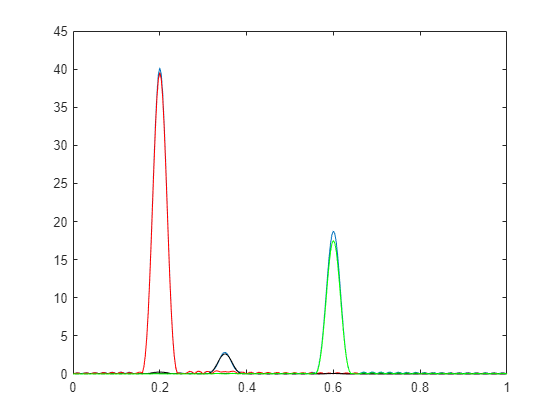

%Representacion en frecuencia
YlButter=fDTFT(ylButter.*hamming(N)',n,w);
YbButter=fDTFT(ybButter.*hamming(N)',n,w);
YhButter=fDTFT(yhButter.*hamming(N)',n,w);
subplot(111);plot(w/pi,abs(X),w/pi,abs(YlButter),'r',w/pi,abs(YbButter),'black',w/pi,abs(YhButter),'g');

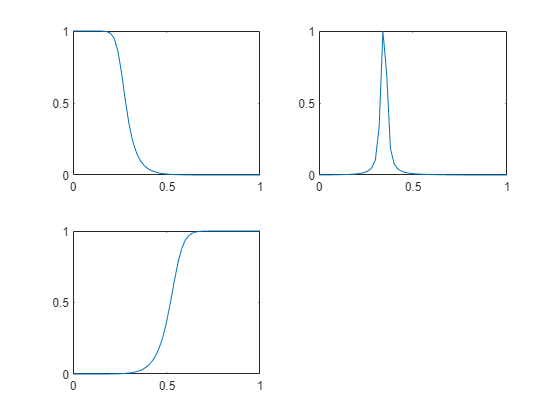

%Representacion filtro
HlButter=fft(hlButter);
HbButter=fft(hbButter);
HhButter=fft(hhButter);
subplot(221);plot(n*2/N,abs(HlButter));axis([0 1 0 1]);subplot(222);plot(n*2/N,abs(HbButter));axis([0 1 0 1]);subplot(223);plot(n*2/N,abs(HhButter));axis([0 1 0 1]);

Filtro Chebyshev tipo I

%Primero orden del filtro, el rizado de la banda de paso, frecuencia de
%paso normalizada
[b,a]=cheby1(7,0.5,0.22); %Filtro paso bajo, el grado modifica el desfase, asique se puede ajustar grado para evitar desfase, pero creo que no es importante
hlCheby1=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Nh=max(find(abs(hlCheby1)>max(hlCheby1)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
ylCheby1=filter(b,a,xe);
ylCheby1=ylCheby1(Nh:Ne);
[b,a]=cheby1(2,0.2,[0.34,0.36]); %Filtro paso banda, para banda eliminada añades "stop"
hbCheby1=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Nh=max(find(abs(hbCheby1)>max(hbCheby1)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
ybCheby1=filter(b,a,xe);
ybCheby1=ybCheby1(Nh:Ne);
[b,a]=cheby1(5,0.7,0.57,"high"); %Filtro paso alto
hhCheby1=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


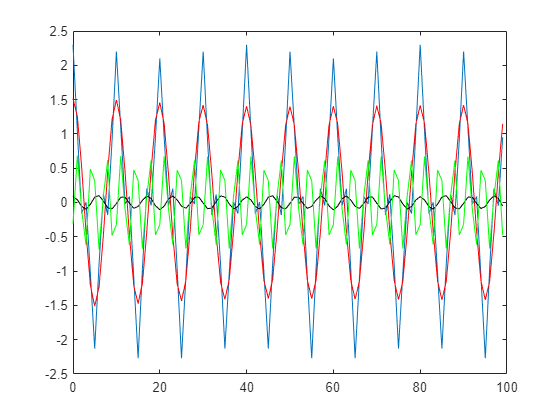

Nh=max(find(abs(hhCheby1)>max(hhCheby1)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
yhCheby1=filter(b,a,xe);
yhCheby1=yhCheby1(Nh:Ne);
%Representacion en tiempo
subplot(111);plot(n,x,n,ylCheby1,'r',n,ybCheby1,'black',n,yhCheby1,'g'); 

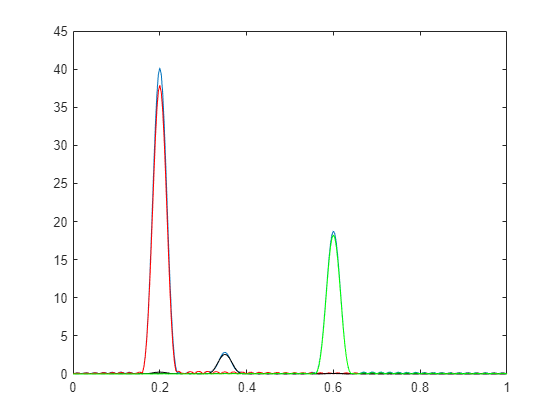

%Representacion en frecuencia
YlCheby1=fDTFT(ylCheby1.*hamming(N)',n,w);
YbCheby1=fDTFT(ybCheby1.*hamming(N)',n,w);
YhCheby1=fDTFT(yhCheby1.*hamming(N)',n,w);
subplot(111);plot(w/pi,abs(X),w/pi,abs(YlCheby1),'r',w/pi,abs(YbCheby1),'black',w/pi,abs(YhCheby1),'g');

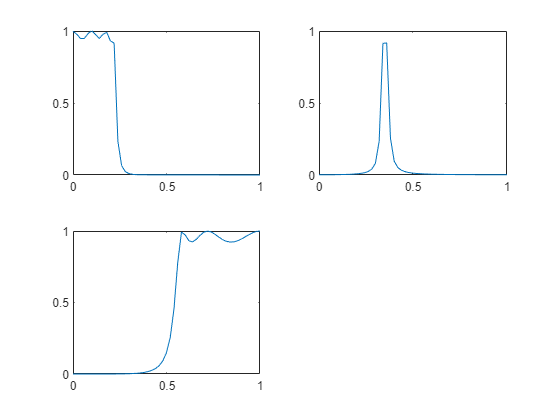


%Representacion filtro
HlCheby1=fft(hlCheby1);
HbCheby1=fft(hbCheby1);
HhCheby1=fft(hhCheby1);
subplot(221);plot(n*2/N,abs(HlCheby1));axis([0 1 0 1]);subplot(222);plot(n*2/N,abs(HbCheby1));axis([0 1 0 1]);subplot(223);plot(n*2/N,abs(HhCheby1));axis([0 1 0 1]);

Filtro Chebyshev tipo II

%Primero orden del filtro, rizado de la banda de paso, atenuacion de banda eliminada, frecuencia de corte
[b,a]=cheby2(6,15,0.24); %Filtro paso bajo
hlCheby2=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Nh=max(find(abs(hlCheby2)>max(hlCheby2)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
ylCheby2=filter(b,a,xe);
ylCheby2=ylCheby2(Nh:Ne);
[b,a]=cheby2(8,30,[0.32,0.37]); %Filtro paso banda
hbCheby2=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Nh=max(find(abs(hbCheby2)>max(hbCheby2)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
ybCheby2=filter(b,a,xe);
ybCheby2=ybCheby2(Nh:Ne);
[b,a]=cheby2(6,20,0.54,"high"); %Filtro paso alto
hhCheby2=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


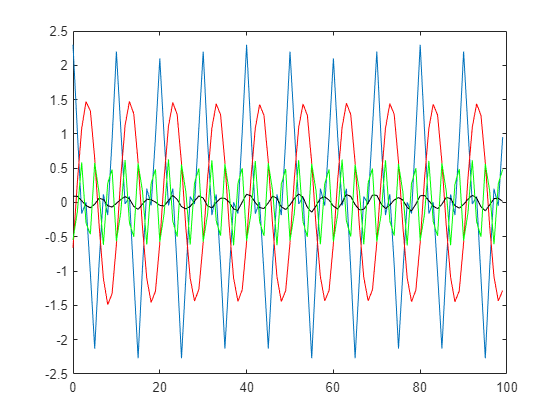

Nh=max(find(abs(hhCheby2)>max(hlCheby2)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
yhCheby2=filter(b,a,xe);
yhCheby2=yhCheby2(Nh:Ne);
%Representacion en tiempo
subplot(111);plot(n,x,n,ylCheby2,'r',n,ybCheby2,'black',n,yhCheby2,'g');

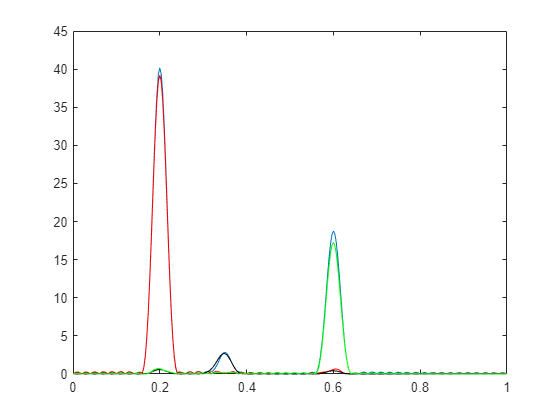

%Representacion en frecuencia
YlCheby2=fDTFT(ylCheby2.*hamming(N)',n,w);
YbCheby2=fDTFT(ybCheby2.*hamming(N)',n,w);
YhCheby2=fDTFT(yhCheby2.*hamming(N)',n,w);
subplot(111);plot(w/pi,abs(X),w/pi,abs(YlCheby2),'r',w/pi,abs(YbCheby2),'black',w/pi,abs(YhCheby2),'g');

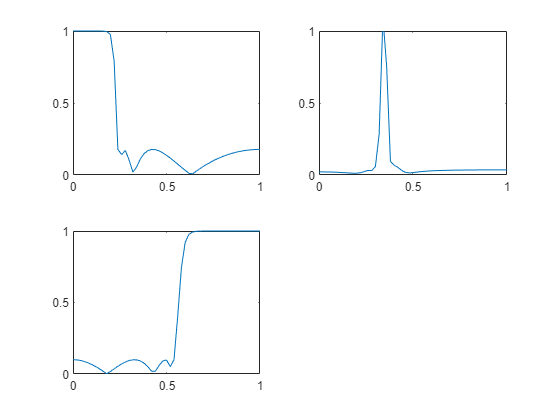

%Representacion filtro
HlCheby2=fft(hlCheby2);
HbCheby2=fft(hbCheby2);
HhCheby2=fft(hhCheby2);
subplot(221);plot(n*2/N,abs(HlCheby2));axis([0 1 0 1]);subplot(222);plot(n*2/N,abs(HbCheby2));axis([0 1 0 1]);subplot(223);plot(n*2/N,abs(HhCheby2));axis([0 1 0 1]);

Filtro Elíptico

%Primero orden del filtro, rizado de la banda de paso, atenuacion de banda eliminada, frecuencia de corte
[b,a]=ellip(4,0.1,25,0.24); %Filtro paso bajo
hlEllip=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Nh=max(find(abs(hlEllip)>max(hlEllip)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
ylEllip=filter(b,a,xe);
ylEllip=ylEllip(Nh:Ne);
[b,a]=ellip(2,2,50,[0.33,0.36]); %Filtro paso banda
hbEllip=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Nh=max(find(abs(hbEllip)>max(hbEllip)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
ybEllip=filter(b,a,xe);
ybEllip=ybEllip(Nh:Ne);
[b,a]=ellip(4,0.3,30,0.57,"high"); %Filtro paso alto
hhEllip=filter(b,a,fDelta(n,0));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


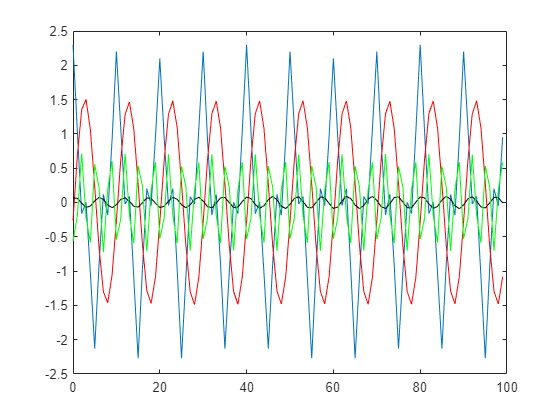

Nh=max(find(abs(hhEllip)>max(hhEllip)/20)); 
Ne=N+Nh-1;
ne=linspace(-Nh+1,N-1,Ne);
xe=1.5*cos(0.2*pi*ne)+0.1*cos(0.35*pi*ne)+0.7*cos(0.6*pi*ne);
yhEllip=filter(b,a,xe);
yhEllip=yhEllip(Nh:Ne);
%Representacion en tiempo
subplot(111);plot(n,x,n,ylEllip,'r',n,ybEllip,'black',n,yhEllip,'g');

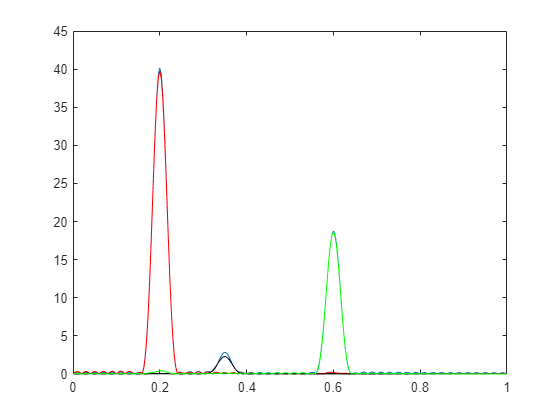

%Representacion en frecuencia
YlEllip=fDTFT(ylEllip.*hamming(N)',n,w);
YbEllip=fDTFT(ybEllip.*hamming(N)',n,w);
YhEllip=fDTFT(yhEllip.*hamming(N)',n,w);
subplot(111);plot(w/pi,abs(X),w/pi,abs(YlEllip),'r',w/pi,abs(YbEllip),'black',w/pi,abs(YhEllip),'g');

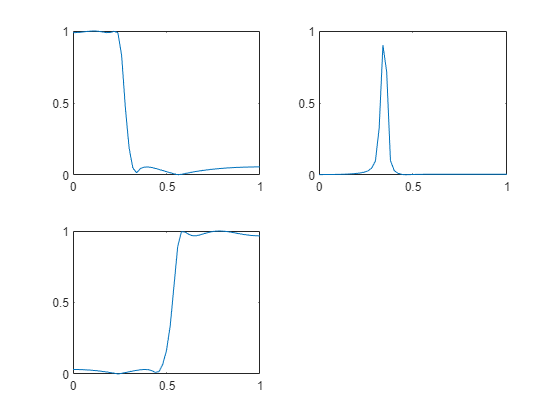

%Representacion filtro
HlEllip=fft(hlEllip);
HbEllip=fft(hbEllip);
HhEllip=fft(hhEllip);
subplot(221);plot(n*2/N,abs(HlEllip));axis([0 1 0 1]);subplot(222);plot(n*2/N,abs(HbEllip));axis([0 1 0 1]);subplot(223);plot(n*2/N,abs(HhEllip));axis([0 1 0 1]);

Señales:

Detectar picos

%Si aparece de esto hacerlo copiando lo que tiene el en serie de tonos, En
%el ecg.mlx esta todo hecho, copiar